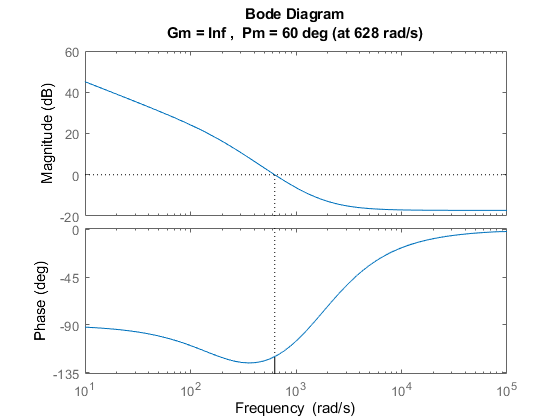

mech.L = 0.5;
mech.l = 0.1;
mech.h = 0.5;
mech.H = 0.3;
mech.L = 1;
mech.hp = 0.2;

% physics constants
const.g = 9.81;
const.rad2deg = 180/pi;
const.deg2rad = 1/const.rad2deg;

% H bridge
driver.kc = 1;
driver.Tc = 2e-9;

% DC stepper motor
stepper.La = 1.6e-3;
stepper.Ra = 2.5;
stepper.Km = 0.18;
stepper.tausf = 0;
stepper.Jeq = 5.5e-6;
stepper.Beq = 2.5e-9;
stepper.Nr = 100;
stepper.p = 2;
stepper.pp = stepper.Nr/stepper.p;
stepper.precision = 360/(stepper.p*stepper.Nr);
stepper.precision2 = stepper.precision/2;

stepper.Tstep = 2e-2;

% arduino
arduino.arch = 8;
arduino.vcc = 5;
arduino.gnd = 0;
arduino.adc.n_bits = 10;
arduino.adc.q_step = (arduino.vcc - arduino.gnd)/(2^(arduino.adc.n_bits));
arduino.adc.fc = 9615;

% controller design (PID with emulation method)
s = tf('s');
P = stepper.precision2*(1-stepper.Tstep/2)/(1+s*stepper.Tstep/2);
[controller.angle.Kp, controller.angle.Ki, controller.angle.Kd] = getPIDBodeFreq(P,100,60,4);
C = controller.angle.Kp + controller.angle.Ki/s + controller.angle.Kd*s;
margin(C*P)

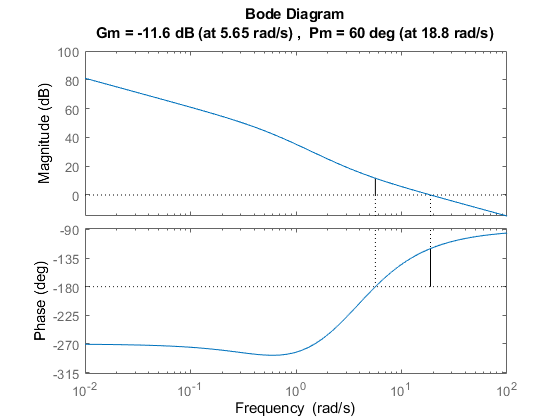

controller.angle.Kw  = 5/stepper.Tstep;
W = C*P/(1+C*P);
A = [0 1;0 0];
B = [0;-(5/3)*const.g*mech.l/mech.L];
C = [1 0];
poles=[-1 -2];
controller.pos.K = place(A,B,poles);
sys = ss(A+B*controller.pos.K,B,C,0);
P = tf(sys);
[controller.pos.Kp, controller.pos.Ki, controller.pos.Kd] = getPIDBodeFreq(P,3,60,4);
C = controller.pos.Kp + controller.pos.Ki/s + controller.pos.Kd*s;
margin(C*P)

controller.pos.Kw  = 5/stepper.Tstep;

%% Definition of Bode Method
% set of utility routines

function [wgc, phim] = getWgcPhim(Mp, ts)
    delta = log(1/Mp)/sqrt(pi^2+log(1/Mp)^2);
    wgc = 3/delta/ts;
    phim = 180/pi*atan(2*delta/sqrt(sqrt(1+4*delta^4)-2*delta^2));
end

function [Kp,Ki,Kd] = getPIDBodeFreq(plant, freq, phim, alpha)
    wgc = 2*pi*freq;
    [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha);
end

function [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha)
    [mag, phase] = bode(plant, wgc);
    DeltaK = 1 / mag;
    DeltaPhi = -180 + phim - phase;
    tmp = tand(DeltaPhi);
    Td = (tmp + sqrt(tmp^2 + 4/alpha))/(2*wgc);
    Ti = alpha * Td;
    Kp = DeltaK * cosd(DeltaPhi);
    Ki = Kp / Ti;
    Kd = Kp * Td;
    s = tf('s');
    C = Kp + Ki * (1/s) + Kd * s;
    [a,b,c,d] = margin(C*plant);
    delta_wgc = d - wgc;
    delta_phim = b - phim;
    assert(delta_wgc < 0.01, "failed to build PID");
    assert(delta_phim < 0.01, "failed to build PID");
end